subject = "data/S001/S001";
rec = 4;
record = [];
for i=0:2
    record = [record string(num2str(rec+i*4, '%02d'))]
end

record = "04"

record = 1×2 string array
    "04"    "08"


record = 1×3 string array
    "04"    "08"    "12"



t1s = cell(0);
t2s = cell(0);

for i=1:numel(record)
    recName = strcat(subject, "R", record(i), ".edf");
    recName = convertStringsToChars(recName);
    disp(recName);

    [eeg, fs, ~] = rdsamp(recName, 1:64);

    [~, T1, T2] = getIntervals(recName, 'event', fs, size(eeg,1));

    eeg = eeg.';

    for j = 1:size(T1, 1)
        segment = eeg(:, T1(j, 1):T1(j, 2));
        t1s{end + 1} = segment;
    end

    for j = 1:size(T2, 1)
        segment = eeg(:, T2(j, 1):T2(j, 2));
        t2s{end + 1} = segment;
    end

end

data/S001/S001R04.edf
data/S001/S001R08.edf
data/S001/S001R12.edf


featF = 'featureVectors.txt';
clasF = 'referenceClass.txt';
fvf = fopen(featF, "wt");
rcf = fopen(clasF, "wt");

f = [0 8 8 13 13 fs/2]/(fs/2);
a = [0 0 1 1 0 0];
n = 35;
b = firls(n, f, a);

[W] = f_CSP(cell2mat(t1s(1)), cell2mat(t2s(1)));
t1s(1) = [];
t2s(1) = [];

lvt1 = cell(size(t1s));
lvt2 = cell(size(t2s));

p = 8;

for i = 1:numel(t1s)
    cst = W * cell2mat(t1s(i));
    cse = [cst(1, :).', cst(size(cst, 1), :).'].';
    csf = filter(b, 1, cse);
    
    AR_features = [];
    AR_order = min(p, size(csf, 1) - 1);
    for j = 1:size(csf, 2)
        AR_coeffs = arburg(csf(:, j), AR_order);
        AR_features = [AR_features; AR_coeffs'];
    end

    lvt1{i} = [log(var(csf(1, :))), log(var(csf(2, :))), AR_features(:)'];
end

for i = 1:numel(t2s)
    cst = W * cell2mat(t2s(i));
    cse = [cst(1, :).', cst(size(cst, 1), :).'].';
    csf = filter(b, 1, cse);
    
    AR_features = [];
    AR_order = min(p, size(csf, 1) - 1);
    for j = 1:size(csf, 2)
        AR_coeffs = arburg(csf(:, j), AR_order);
        AR_features = [AR_features; AR_coeffs'];
    end

    lvt2{i} = [log(var(csf(1, :))), log(var(csf(2, :))), AR_features(:)'];
end

for i = 1:numel(lvt1) - 1
    fprintf(fvf, '%.8f %.8f', lvt1{i}(1), lvt1{i}(2));
    for k = 3:numel(lvt1{i})
        fprintf(fvf, ' %.8f', lvt1{i}(k));
    end
    fprintf(fvf, '\n');
    fprintf(rcf, 'T1\n');
end

for i = 1:numel(lvt2) - 1
    fprintf(fvf, '%.8f %.8f', lvt2{i}(1), lvt2{i}(2));
    for k = 3:numel(lvt2{i})
        fprintf(fvf, ' %.8f', lvt2{i}(k));
    end
    fprintf(fvf, '\n');
    fprintf(rcf, 'T2\n');
end


fclose(fvf);
fclose(rcf);

Size: 41x1314; EVENT: T1; NON-EVENT: T2
LDA
   All records-Test   TP= 19 FN=  2; FP=  1 TN= 19; Se:  90.48 Sp:  95.00 CA:  92.68 AUC:  94.52
   All records-Learn  TP= 19 FN=  2; FP=  1 TN= 19; Se:  90.48 Sp:  95.00 CA:  92.68 AUC:  94.52
   20% holdout-Test  Single  TP=  2 FN=  2; FP=  3 TN=  1; Se:  50.00 Sp:  25.00 CA:  37.50 AUC:  12.50
   20% holdout-Learn Single  TP=  2 FN=  2; FP=  3 TN=  1; Se:  50.00 Sp:  25.00 CA:  37.50 AUC:  93.75
     20% holdout-Test  Nrep  TP=  2 FN=  2; FP=  2 TN=  2; Se:  50.00 Sp:  50.00 CA:  50.00 AUC:  54.25
     20% holdout-Learn Nrep  TP=  2 FN=  2; FP=  2 TN=  2; Se:  50.00 Sp:  50.00 CA:  50.00 AUC:  90.77
   Cross-valid-Test  Single  TP= 12 FN=  9; FP= 12 TN=  8; Se:  57.14 Sp:  40.00 CA:  48.78 AUC:  51.19
   Cross-valid-Learn Single  TP= 12 FN=  9; FP= 12 TN=  8; Se:  57.14 Sp:  40.00 CA:  48.78 AUC:  92.66


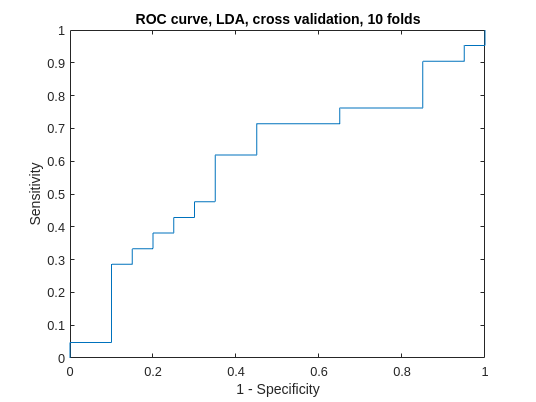

     Cross-valid-Test  Nrep  TP= 13 FN=  9; FP= 10 TN= 10; Se:  59.09 Sp:  50.00 CA:  54.76 AUC:  55.51
     Cross-valid-Learn Nrep  TP= 13 FN=  9; FP= 10 TN= 10; Se:  59.09 Sp:  50.00 CA:  54.76 AUC:  92.43
   Leave one o-Test   TP= 12 FN=  9; FP=  9 TN= 11; Se:  57.14 Sp:  55.00 CA:  56.10 AUC:  54.76
   Leave one o-Learn  TP= 12 FN=  9; FP=  9 TN= 11; Se:  57.14 Sp:  55.00 CA:  56.10 AUC:  94.01
QDA
   All records-Test   TP= 21 FN=  0; FP= 20 TN=  0; Se: 100.00 Sp:   0.00 CA:  51.22 AUC:   0.00
   All records-Learn  TP= 21 FN=  0; FP= 20 TN=  0; Se: 100.00 Sp:   0.00 CA:  51.22 AUC:   0.00
   20% holdout-Test  Single  TP=  4 FN=  0; FP=  4 TN=  0; Se: 100.00 Sp:   0.00 CA:  50.00 AUC:  28.12
   20% holdout-Learn Single  TP=  4 FN=  0; FP=  4 TN=  0; Se: 100.00 Sp:   0.00 CA:  50.00 AUC:   0.00
     20% holdout-Test  Nrep  TP=  4 FN=  0; FP=  4 TN=  0; Se: 100.00 Sp:   0.00 CA:  50.00 AUC:  47.50
     20% holdout-Learn Nrep  TP=  4 FN=  0; FP=  4 TN=  0; Se: 100.00 Sp:   0.00 CA:  50

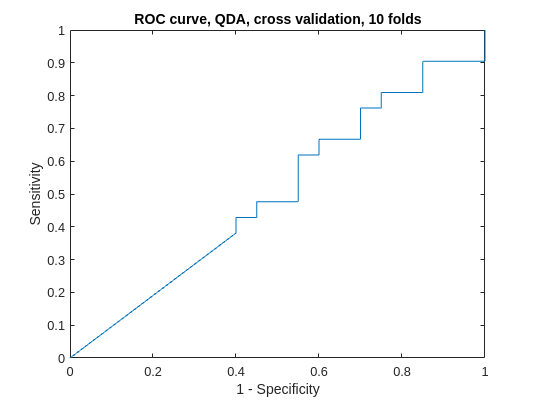

     Cross-valid-Test  Nrep  TP= 20 FN=  1; FP= 19 TN=  1; Se:  95.24 Sp:   5.00 CA:  51.22 AUC:  49.65
     Cross-valid-Learn Nrep  TP= 20 FN=  1; FP= 19 TN=  1; Se:  95.24 Sp:   5.00 CA:  51.22 AUC:  11.76
   Leave one o-Test   TP= 21 FN=  0; FP= 20 TN=  0; Se: 100.00 Sp:   0.00 CA:  51.22 AUC:  69.17
   Leave one o-Learn  TP= 21 FN=  0; FP= 20 TN=  0; Se: 100.00 Sp:   0.00 CA:  51.22 AUC:   3.72


doClassification('featureVectors.txt', 'referenceClass.txt', {1, 1}, 10, 50, 0)